Consider a pendulum subject to external harmonic moment, which is governed by


$$\ddot{\theta}+c\dot{\theta}+\sin\theta=\epsilon\cos\Omega t$$


Define $x_1=\theta$, $x_2=\dot{\theta}$, $x_3=\sin\theta$ and $x_4=\cos\theta-1$, we have


$$\dot{x}_1=x_2,\\
\dot{x}_2=-cx_2-x_3+\epsilon\cos\Omega t,\\
\dot{x}_3=(1+x_4)x_2,\\
x_3^2+(1+x_4)^2=1.$$


Lyapunov subcenter manifold

clear all
c=0.001;
B = diag([1 1 1 0]);
A = [0 1 0 0;0 -c -1 0;0 1 0 0;0 0 0 2];
subs2 = [3 2 4
    4 3 3
    4 4 4];
vals2 = [1 1 1]';
F2 = sptensor(subs2,vals2,[4 4 4]);

## Setup model

DS = DynamicalSystem();
set(DS,'B',B,'A',A,'fnl',{F2});
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

**Linear Modal analysis**

[V,D,W] = DS.linear_spectral_analysis();

1 nan/inf eigenvalues are removed
1 zero eigenvalues are removed

 The first 2 nonzero eigenvalues are given as 
  -0.0005 + 1.0000i
  -0.0005 - 1.0000i



## Autonomous SSM 

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2]; % choose master spectral subspace
order = 35;                  % SSM expansion order
S.choose_E(resonant_modes)

sigma_out = 0
sigma_in = 1


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 3.09E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.29E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.46E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.80E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.12E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 4.65E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 5.18E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 5.95E-02 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 6.73E-02 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 7.78E-02 MB
Manifold computation time 

#### Reduced dynamics in symbolic form

lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 2.045\,{\rho_{1}}^{35}+1.027\,{\rho_{1}}^{33}+0.5184\,{\rho_{1}}^{31}+0.2632\,{\rho_{1}}^{29}+0.1344\,{\rho_{1}}^{27}+0.06919\,{\rho_{1}}^{25}+0.03592\,{\rho_{1}}^{23}+0.01883\,{\rho_{1}}^{21}+0.009996\,{\rho_{1}}^{19}+0.005383\,{\rho_{1}}^{17}+0.002951\,{\rho_{1}}^{15}+0.001656\,{\rho_{1}}^{13}+0.0009584\,{\rho_{1}}^{11}+0.0005789\,{\rho_{1}}^{9}+0.0003731\,{\rho_{1}}^{7}+0.000269\,{\rho_{1}}^{5}+0.0002498\,{\rho_{1}}^{3}-0.0005\,\rho_{1}\\ -686.8\,{\rho_{1}}^{34}-347.6\,{\rho_{1}}^{32}-177.0\,{\rho_{1}}^{30}-90.73\,{\rho_{1}}^{28}-46.88\,{\rho_{1}}^{26}-24.44\,{\rho_{1}}^{24}-12.88\,{\rho_{1}}^{22}-6.873\,{\rho_{1}}^{20}-3.725\,{\rho_{1}}^{18}-2.058\,{\rho_{1}}^{16}-1.165\,{\rho_{1}}^{14}-0.681\,{\rho_{1}}^{12}-0.4159\,{\rho_{1}}^{10}-0.2709\,{\rho_{1}}^{8}-0.1957\,{\rho_{1}}^{6}-0.1715\,{\rho_{1}}^{4}-0.2498\,{\rho_{1}}^{2}+1.0 \end{array}\right)$$

Symbolic string to latex 

% sympref('FloatingPointOutput',true);
% rho1dot = latex(y(1))
% theta1dot = latex(y(2))

Convergence of backbone curve

% 3.467*rho_1^6 - 8.963*rho_1^4 + 0.8168*rho_1^2 + 2.0
syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

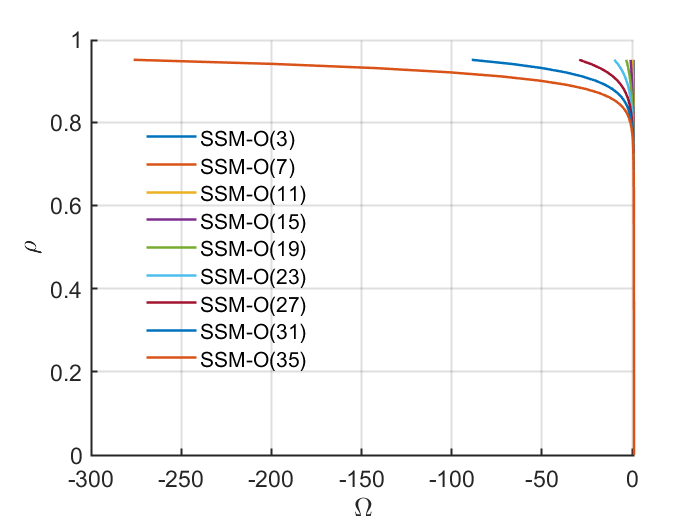

rhosamp = 0:0.01:0.95;
% orders = [3 5 7 9 11 13];
orders = [3 7 11 15 19 23 27 31 35];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

#### Transient response validation

We take an initial condition on SSM and perform forward simulation using both the reduced-order model and the full model

tf = 50;
nsteps = 1000;
q0 = 0.5*exp(1i*0);
q0 = [q0;conj(q0)];
z0 = reduced_to_full_traj(0,q0,W0);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, 1:4, [], q0);

Reference solution from forward simulation

options = odeset('RelTol',1e-8,'AbsTol',1e-10,'Events',@zero_crossing_event);
[tInt1, zInt1,te,ye] = ode15s(@(t,x) pend_ode_auto(x,0), [0 tf], z0(1:2),options); % Transients

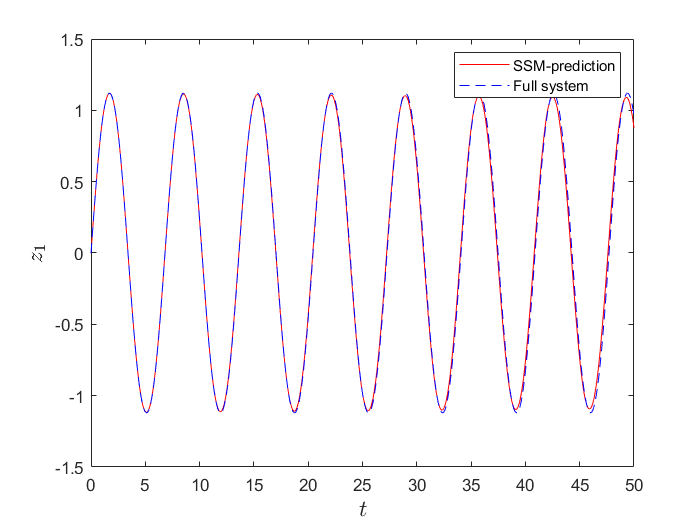

figure;
plot(traj.time,traj.phy(:,1),'r-'); hold on
plot(tInt1,zInt1(:,1),'b--');
legend('SSM-prediction','Full system')
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$z_1$','Interpreter',"latex",'FontSize',14);

#### Backbone curve 

#### SSM prediction

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.02E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.00E-03 MB
gamma = 
   0.0002 - 0.2498i



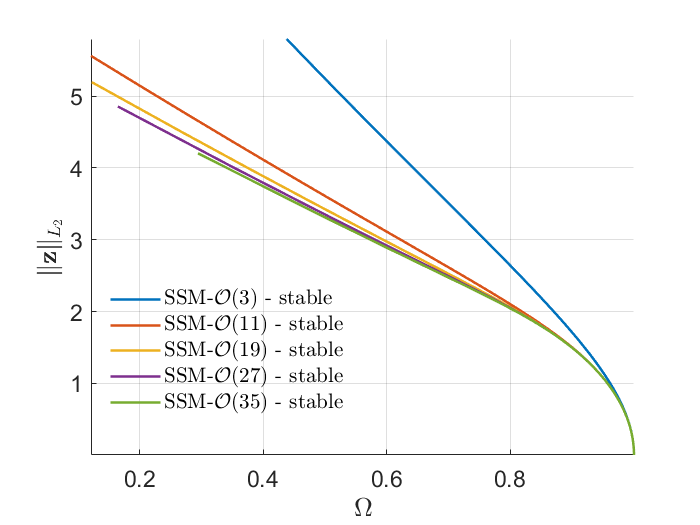

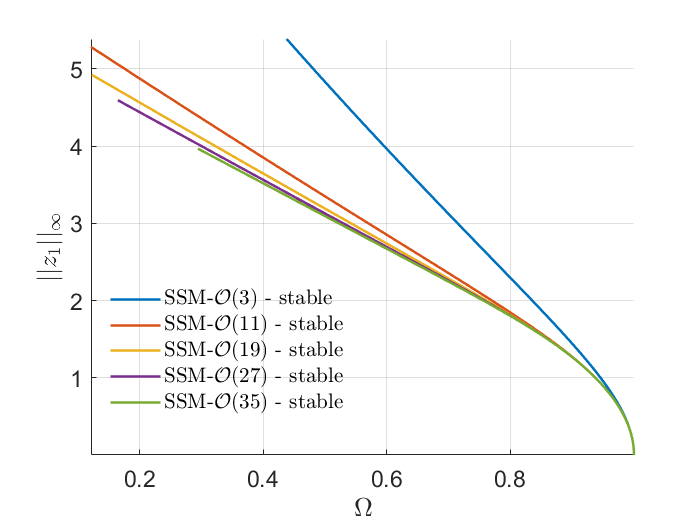

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.15E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.35E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.52E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.86E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 2.18E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 2.71E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 3.24E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 4.01E-02 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 4.78E-02 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 5.84E-02 MB
gamma = 
   0.0002 - 0.249

set(S.FRCOptions,'outDOF',1);
freqRange = [0.1 1.1];
rhomax = 1.5;
BB = S.extract_backbone(resonant_modes, freqRange, [3 11 19 27 35],rhomax);

figbc = gcf;

[~,idx1] = min(abs(tInt1-te(1)));
[~,idx2] = min(abs(tInt1-te(2)));

prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 2, 'h_max', 0.5, 'PtMX', 250);
prob = coco_set(prob, 'coll', 'NTST', 20);
prob = coco_set(prob, 'po', 'bifus', 'off');
funcs = {@pend_ode_auto};
coll_args = [funcs, {tInt1(idx1:idx2)-tInt1(idx1), zInt1(idx1:idx2,:), {'c'}, 0}];
prob = ode_isol2po(prob, '', coll_args{:});
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
ampdata.dof  = 1;
ampdata.zdim = 2;
prob = coco_add_func(prob, 'amp1', @amplitude, ampdata, 'regular', 'x1',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);

Tmin = 2*pi/max([BB.Omega]);
Tmax = 2*pi/min([BB.Omega]);
cont_args = {1, {'po.period' 'x1' 'c'}, [0.95*Tmin,1.1*Tmax]};

fprintf('\n Run=''%s'': Continue primary family of periodic orbits.\n', ...
  'freq_resp');


 Run='freq_resp': Continue primary family of periodic orbits.



bd1  = coco(prob, 'auto_freq_resp', [], cont_args{:});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.01e-02  1.45e+01    0.0    0.0    0.0
   1   1  1.00e+00  3.28e-02  7.04e-06  1.45e+01    0.0    0.0    0.0
   2   1  1.00e+00  4.10e-05  3.93e-12  1.45e+01    0.0    0.0    0.0
   3   1  1.00e+00  2.05e-11  3.49e-15  1.45e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE     po.period           x1            c
    0  00:00:00   1.4493e+01      1  EP      6.8146e+00   1.1200e+00  -2.0138e-11
   10  00:00:01   1.8185e+01      2          7.4394e+00   1.5843e+00   1.6095e-12
   20  00:00:02   2.3932e+01      3          8.7858e+00   2.1442e+00  -6.9035e-12
   30  00:00:02   2.9654e+01      4          1.0785e+01   2.5759e+00  -2.7150e-13
   40  00:00:03   3.4819e+01      5          1.3260e+01   2.8461e+00   1.1048e-13
   50  00:00:03   4.0077e+01      6          1.6028e+01   2.9953e+00  -9.1384e-12
   6

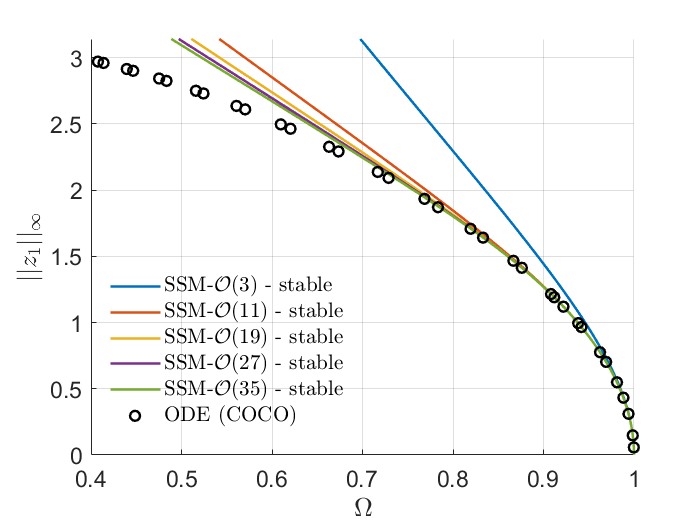

bd1 = coco_bd_read('auto_freq_resp');
figure(figbc); hold on
% plot([BB.Omega],[BB.Aout],'b-'); hold on
% bd = coco_bd_read('backbone_coco');
amp_auto_coco = coco_bd_col(bd1,'x1');
om_auto_coco = 2*pi./coco_bd_col(bd1,'po.period');
plot(om_auto_coco(1:4:end),amp_auto_coco(1:4:end),'ko','LineWidth',1.5,'MarkerSize',6,'DisplayName','ODE (COCO)');
xlim([0.4 1]);
ylim([0,pi]);